# Design of a "type $g=2$" Controller

## Description of the Feedback Control System

Consider the feedback control system described by the block-scheme shown in the following figure   

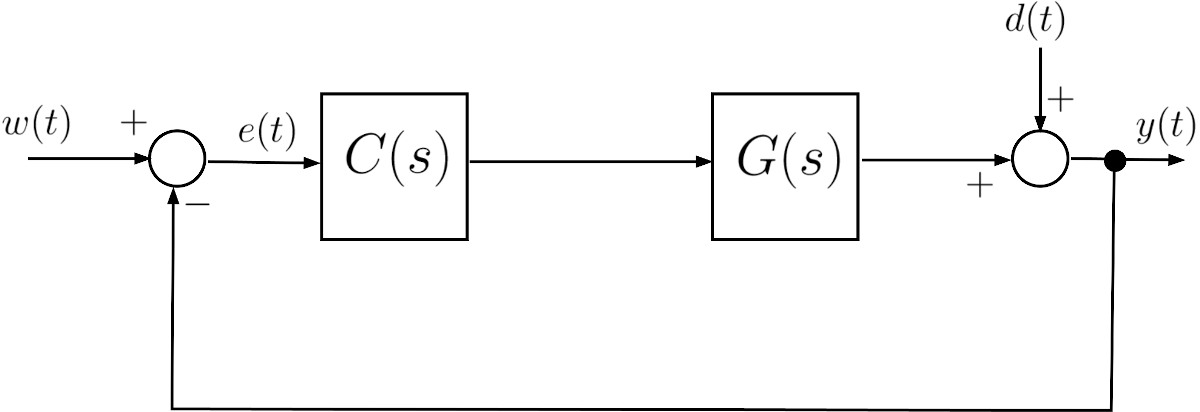	

where $G(s)$ is given by                


$$G(s) = \frac{1.5(1+s)}{s(1+20\,s)}$$
	

## **Question**		

**Q1**: Design a controller $C(s) = \mu_C \, \frac{1+T\,s}{s}$ such that all following requirements are simultaneously met: 

- $\left| e(\infty)\right| \le 0.2$ for $w(t) = t\cdot \mathbf{1}(t)$ and $d(t) = 0$, where $\mathbf{1}(t)$ denotes the unit step function;

- $t_s \le 5 \,\text{s}$  , where $t_s$ is the settling time at $1\,\%$ ; 

- The phase margin satisfies $\varphi_m \ge 60^{\degree}$.

[Excerpt from the written examination on date 2010/06/15]	

## Foreword to the Provided Solution

The proposed problem admits to more than one possible solution. The proposed solution is not the only admissible solution (in fact, the problem admits to infinite solutions), nor is it optimal. It is only a simple solution that can be obtained using the tools available in MATLAB's Control System Toolbox.

You are encouraged to solve the problem by finding alternative solutions and comparing the performance of the control system using your solution with those obtained using the proposed solution in this live script.  				

## Solution 

Let's define the transfer function of the process $G(s)$ and configure the MATLAB Search Path, by adding the folder containing the M-code able to compute and plot the asymptotic approximation of the Bode diagrams of the frequency response of a given transfer function.

clear

% adding folders (and subfolders) to search path
addpath(genpath('BodeDiagram/'))

% let's define the transfer function builder element
s=tf('s');

% the plant transfer function
Gs = 1.5*(1+s)/s/(1+20*s);

## **First Solution Proposal**

### Static Design

- Since it is required to determine a PI-type controller, the open-loop transfer function will certainly have two poles at $s=0$.

- The closed-loop system, if stable, will turn out to be a **type 2 system**: the steady-state error at the ramp will then be zero. 

- The first requirement will then indeed be satisfied.


$$C(s) = \mu_C \, \frac{1+sT}{s}$$


#### Asymptotic Stability

Let's determine the constraints on the parameters $\mu$ and $T$ to guarantee closed-loop asymptotic stability:


$$L(s) = 1.5\,\mu\,\frac{(1+s)\,(1+T\,s)}{s^2\,(1+20\,s)} \quad \Longrightarrow\quad F(s) = \frac{L(s)}{1+L(s)} \quad \Longrightarrow \; p_{F}(s) = 20\,s^3 +\left(1+\frac{3}{2}\,\mu\,T\right)\,s^2+\frac{3}{2}\,\mu\,(1+T)\,s + \frac{3}{2}\,\mu$$


syms x
syms mu T
pF = x^2*(1+20*x) +1.5*mu*(1+x)*(1+T*x);
collect(pF,x)

$$ans = 20\,x^{3}+\left(\frac{3\,T\,\mu }{2}+1\right)\,x^{2}+\left(\frac{3\,\mu }{2}+\frac{3\,T\,\mu }{2}\right)\,x+\frac{3\,\mu }{2}$$

Applying the Routh-Hurwitz criterion to the characteristic closed-loop polynomial leads to the following table


$$\begin{array}{c|cc}
3 & 20 & \frac{3}{2}\,\mu\,(1+T) \\
2& \left(1+\frac{3}{2}\,\mu\,T\right) & \frac{3}{2}\,\mu\\
1& \alpha & \\
0& \frac{3}{2}\,\mu & 
\end{array} \qquad \alpha = \frac{\mu}{2}\,\frac{\big[9\,\mu\,T^2+ 3\left(3 \mu+2\right)\,T -114\big]}{3\,\mu\,T+2}$$


alphaCOEFF = ((1+3*mu*T/2)*(3*mu*(1+T)/2)-20*(3*mu/2))/((1+3*mu*T/2));
collect(simplify(expand(alphaCOEFF)), T)

$$ans = \frac{\left(9\,\mu^{2}\right)\,T^{2}+\left(9\,\mu^{2}+6\,\mu \right)\,T-114\,\mu }{\left(6\,\mu \right)\,T+4}$$

The analysis of the table, also considering the constraints $\mu>0$ , $T>0$, leads to the condition


$$T > \frac{-\left(3\,\mu+2\right) +\sqrt{9\,\mu^2+468\,\mu+4}}{6\,\mu}$$


Conditions for asymptotic stability are:


$$\left\{ \begin{array}{rcl}
T &>& 0 \\
\mu & > & 0 \\
T &>& \frac{-\left(3\,\mu+2\right) +\sqrt{9\,\mu^2+468\,\mu+4}}{6\,\mu}
\end{array} \right.$$


### Dynamic Design

Recall **Part 9 - pag. 40**  of the course material

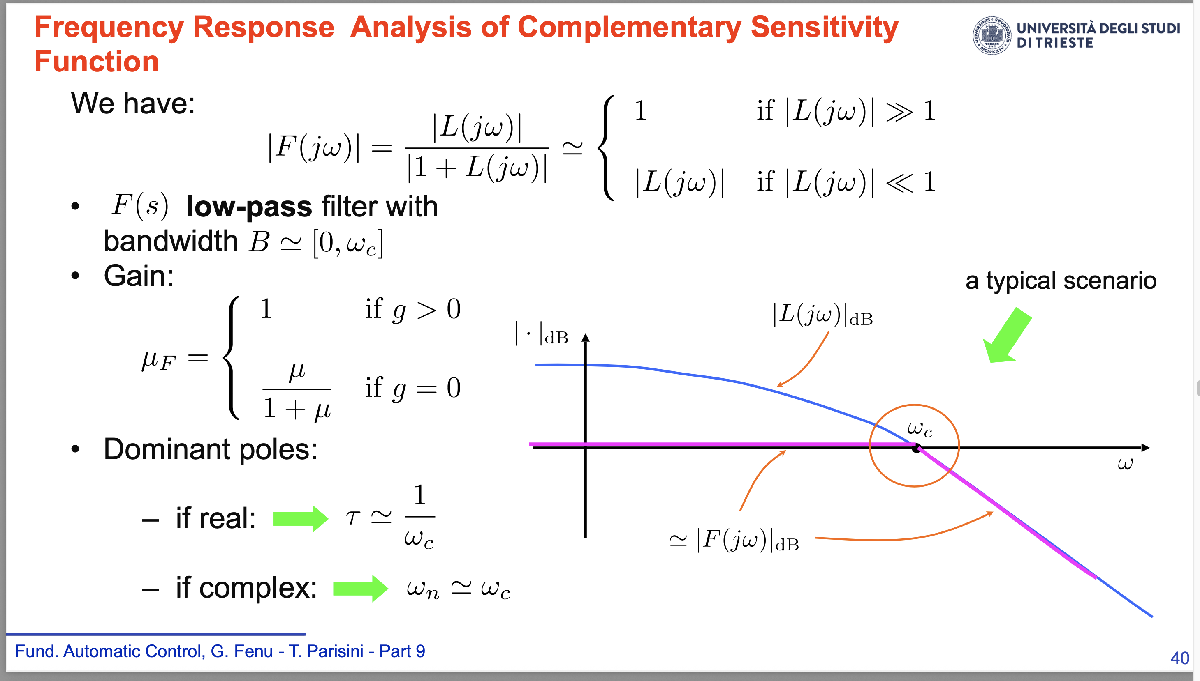

A suﬃciently high phase margin can be chosen so as to be able to assume a closed-loop real pole as the dominant pole:


$$\varphi_m \ge 75^{\circ} \quad \Longrightarrow \quad t_{a\,1\%} \approx 4.6\,\tau$$


Now, by choosing the value of the settling time, one is also able to determine the pulsation $\omega_C$:


$$t_{a\,1\%} =1 \quad \Longrightarrow \quad \tau = \frac{10}{46} \quad \Longrightarrow \quad \omega_C \approx 5\;\text{rad/s}$$


Finally, let's tune the controller's parameters


$$\begin{array}{l}
\begin{array}{rclcl}
\omega_C = 5\,,\; \varphi_m = 75^{\circ} &\Longrightarrow & \angle L(j\,5) = -105^{\circ} &\Longrightarrow & T \\
\omega_C = 5 &\Longrightarrow & \left| L(j\,5) \right| = 1 &\Longrightarrow & \mu
\end{array}
\end{array}$$


This results in


$$\angle L(j\,5) = -105^{\circ} = \arctan 5 + \arctan 5T -180^\circ - \arctan 100 \quad \Longrightarrow \quad T \approx 2.68$$



$$\left\vert L(j\,5)\right\vert = 1 \quad \Longrightarrow \quad \mu \approx 24.30$$


% solving arg L(j5) = -105
a5 = atan(5);
a100 = atan(100);
rad105 = deg2rad(105);
Tval = tan(pi +a100-a5-rad105)/5

Tval = 2.6831

% solving |L(j5)|=1
Ls = Gs*(1+Tval*s)/s


Ls =
 
  4.025 s^2 + 5.525 s + 1.5
  -------------------------
        20 s^3 + s^2
 
Continuous-time transfer function.
Model Properties



LsMAG5 = abs(freqresp(Ls, 1j*5))

LsMAG5 = 0.0412

muVAL = 1/LsMAG5

muVAL = 24.2983

Ls = muVAL*Ls


Ls =
 
  97.79 s^2 + 134.2 s + 36.45
  ---------------------------
         20 s^3 + s^2
 
Continuous-time transfer function.
Model Properties


% the PI controller
Cs = muVAL*(1+Tval*s)/s


Cs =
 
  65.19 s + 24.3
  --------------
        s
 
Continuous-time transfer function.
Model Properties


### Frequency Response

The Bode diagrams of the frequency response of $L(s)$ are:

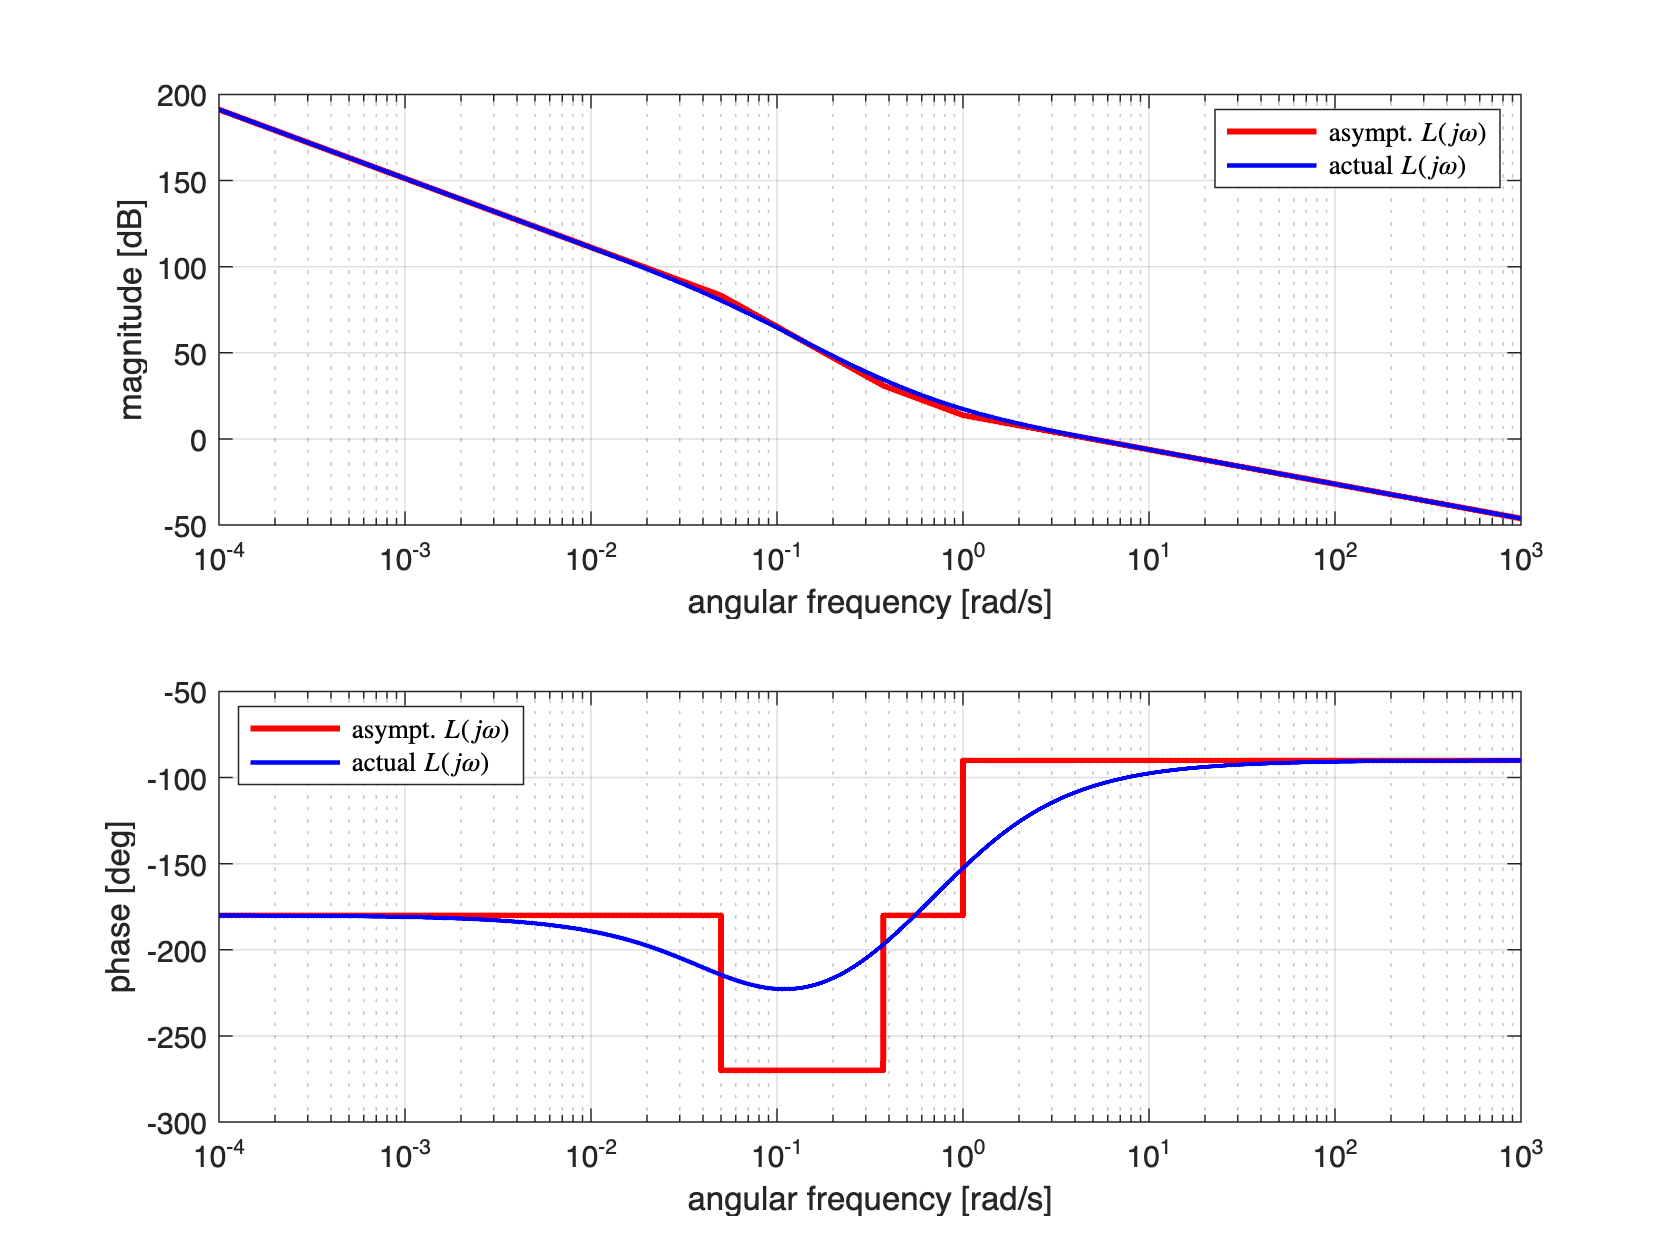

figure('Units','centimeters','Position',[0.5, 0.5, 27,24]);
[ha1, ha2] = drawBodediagrams(Ls);
legend(ha1, 'asympt. $L(j \omega)$', 'actual $L(j \omega)$', ...
        'Interpreter', 'latex', 'location', 'best')
legend(ha2, 'asympt. $L(j \omega)$', 'actual $L(j \omega)$', ...
        'Interpreter', 'latex', 'location', 'best')

Finally, the gain and phase margins assume the values

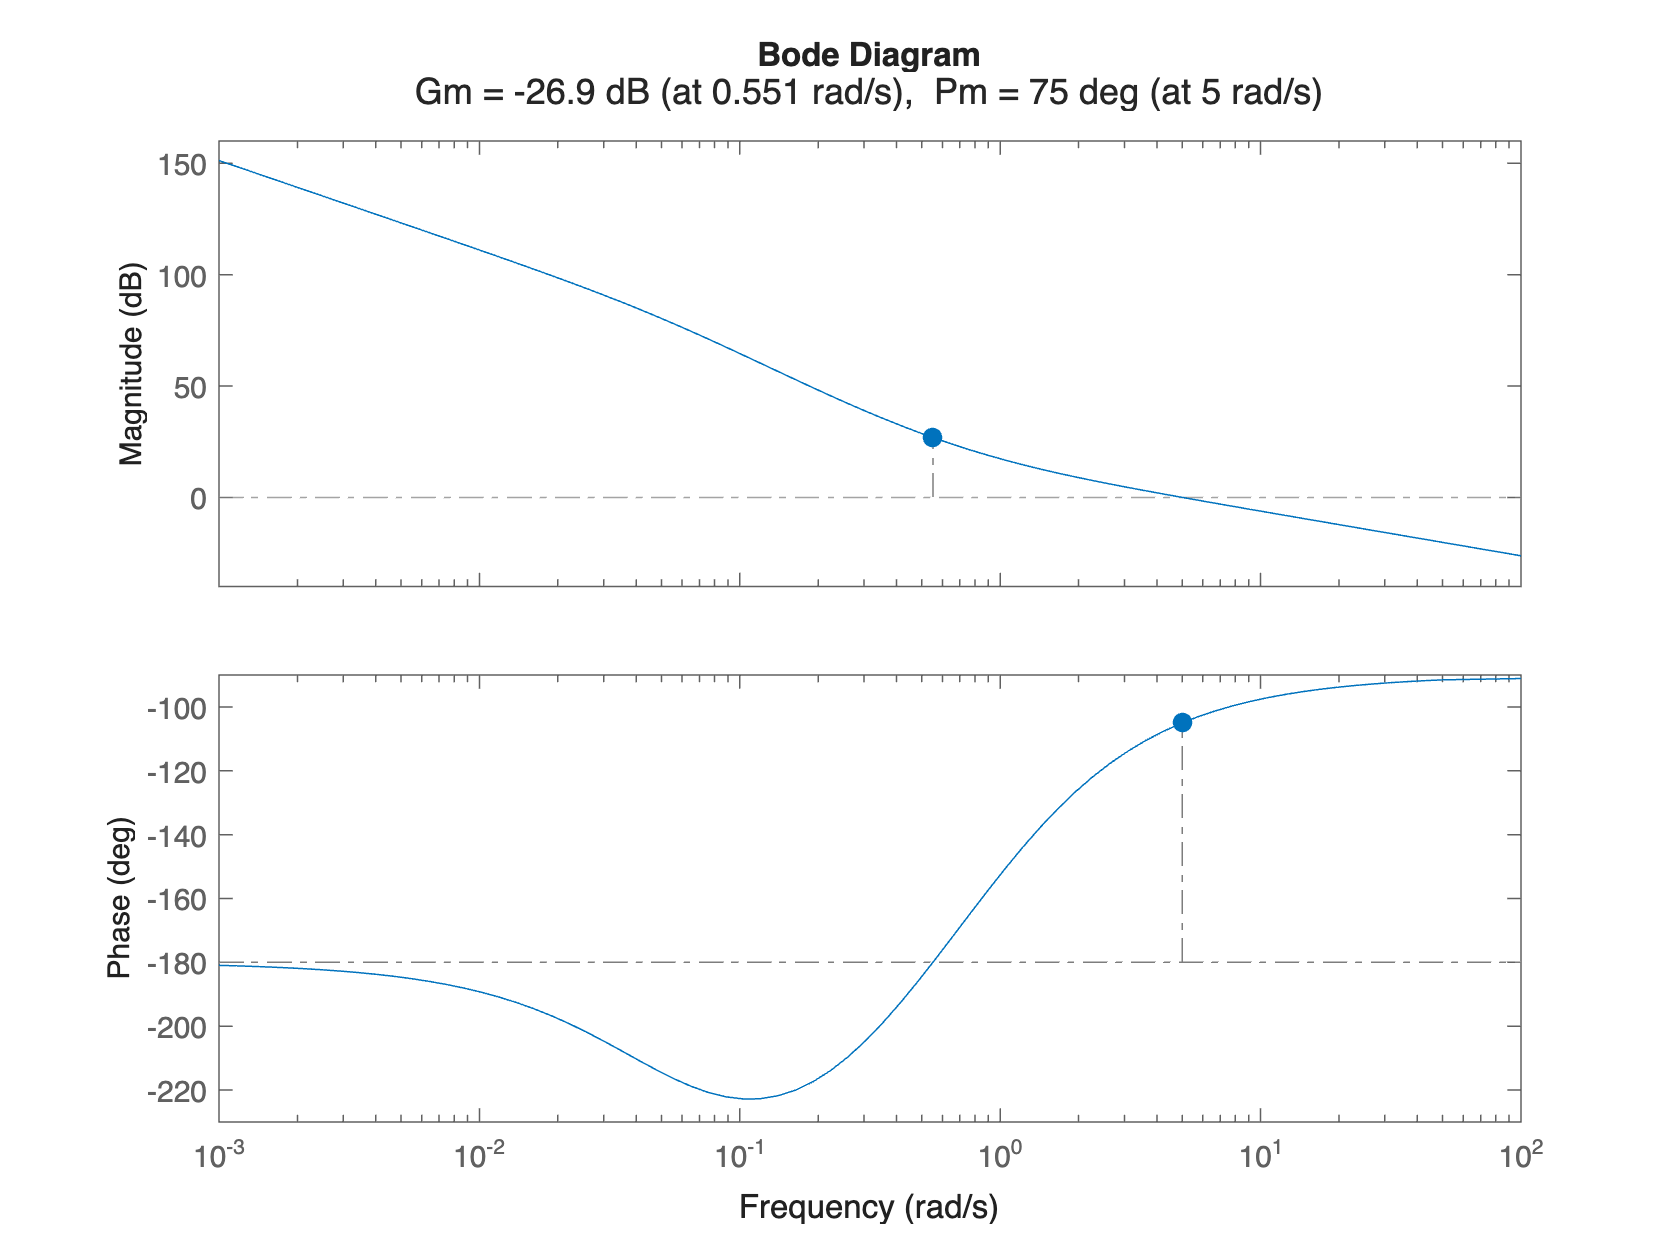

figure;margin(Ls)

### Fine Tuning Using the ControlSystemDesigner

controlSystemDesigner(Gs, Cs)

There is no need to further tuning of the controller. 

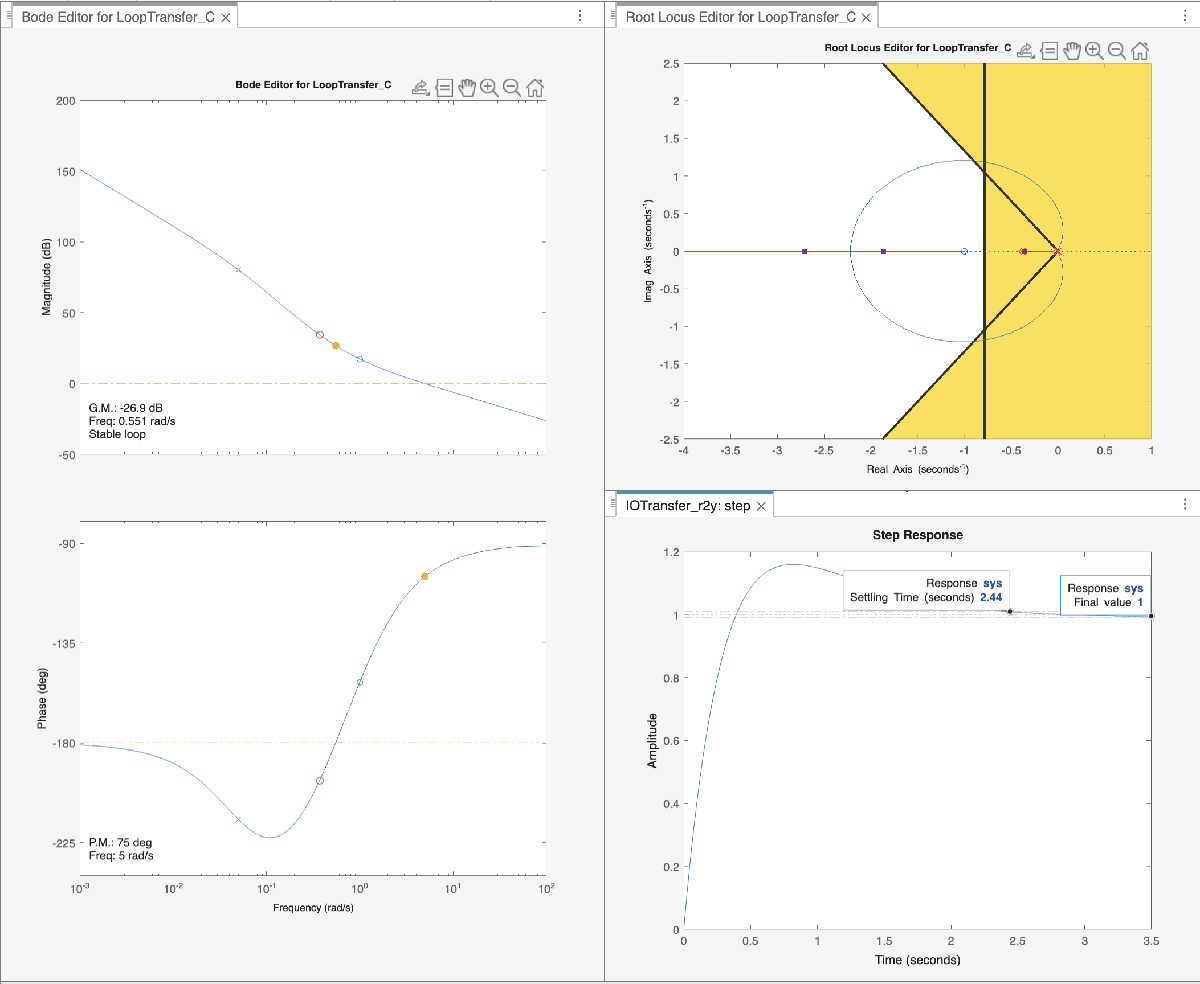

The session MAT file corresponding to the Figure is `SOL1_controlSysDesignerSession.mat` .

## A Second Solution Proposal

One can choose in advance to set the zero of the controller $C(s)$ transfer function (i.e., the value of $T$ ), by cancelling a pole of the process transfer function $G(s)$:


$$C(s) = \mu\,\frac{1+20\,s}{s} \quad \Longrightarrow \quad L(s) = \frac{3\,\mu}{2}\,\frac{1+s}{s^2}$$


The gain constant of the controller $\mu$ must be chosen so as to ensure the asymptotic stability of the closed-loop system. The closed-loop polynomial results in


$$p_F(s) = s^2+1.5\,\mu\,s + 1.5\,\mu$$


By applying the Routh-Hurwitz criterion, it is easy to state that closed-loop stability is guaranteed as long as $\mu >0$.

The desired phase margin is now imposed, and the pulsation $\omega_C$ is determined.


$$ \varphi_m = 75^{\circ} \quad \Longrightarrow \quad \angle L(j\,\omega_C) = -105^{\circ} = \arctan \omega_c -180^\circ \quad \Longrightarrow \quad \omega_C \approx 3.73\;\text{rad/s}$$


% solving arg L(omC) = -105, looking for omC
omCval = tan(pi-rad105)

omCval = 3.7321

What about the settling time requirement?

t_a1 = 4.6/omCval

t_a1 = 1.2326

Thus, all the requirements are met.

 Finally, the value of the gain constant $\mu$ is computed.


$$\bar \omega_c = 3.73 \quad \Longrightarrow \quad \left\vert L(j\,\bar \omega_c)\right\vert = 1 \quad \Longrightarrow \quad \mu \approx 2.40$$


% solving |L(j*omCval)|=1
Ls2 = 1.5*(1+s)/s/s;

LsMAGomC = abs(freqresp(Ls2, 1j*omCval));
muVAL = 1/LsMAGomC

muVAL = 2.4033


Ls2 = muVAL*Ls2;


The controller results in

Cs2 = muVAL * (1+20*s)/s


Cs2 =
 
  48.07 s + 2.403
  ---------------
         s
 
Continuous-time transfer function.
Model Properties


### Frequency Response

The Bode diagrams of the frequency response of $L(s)$ are:

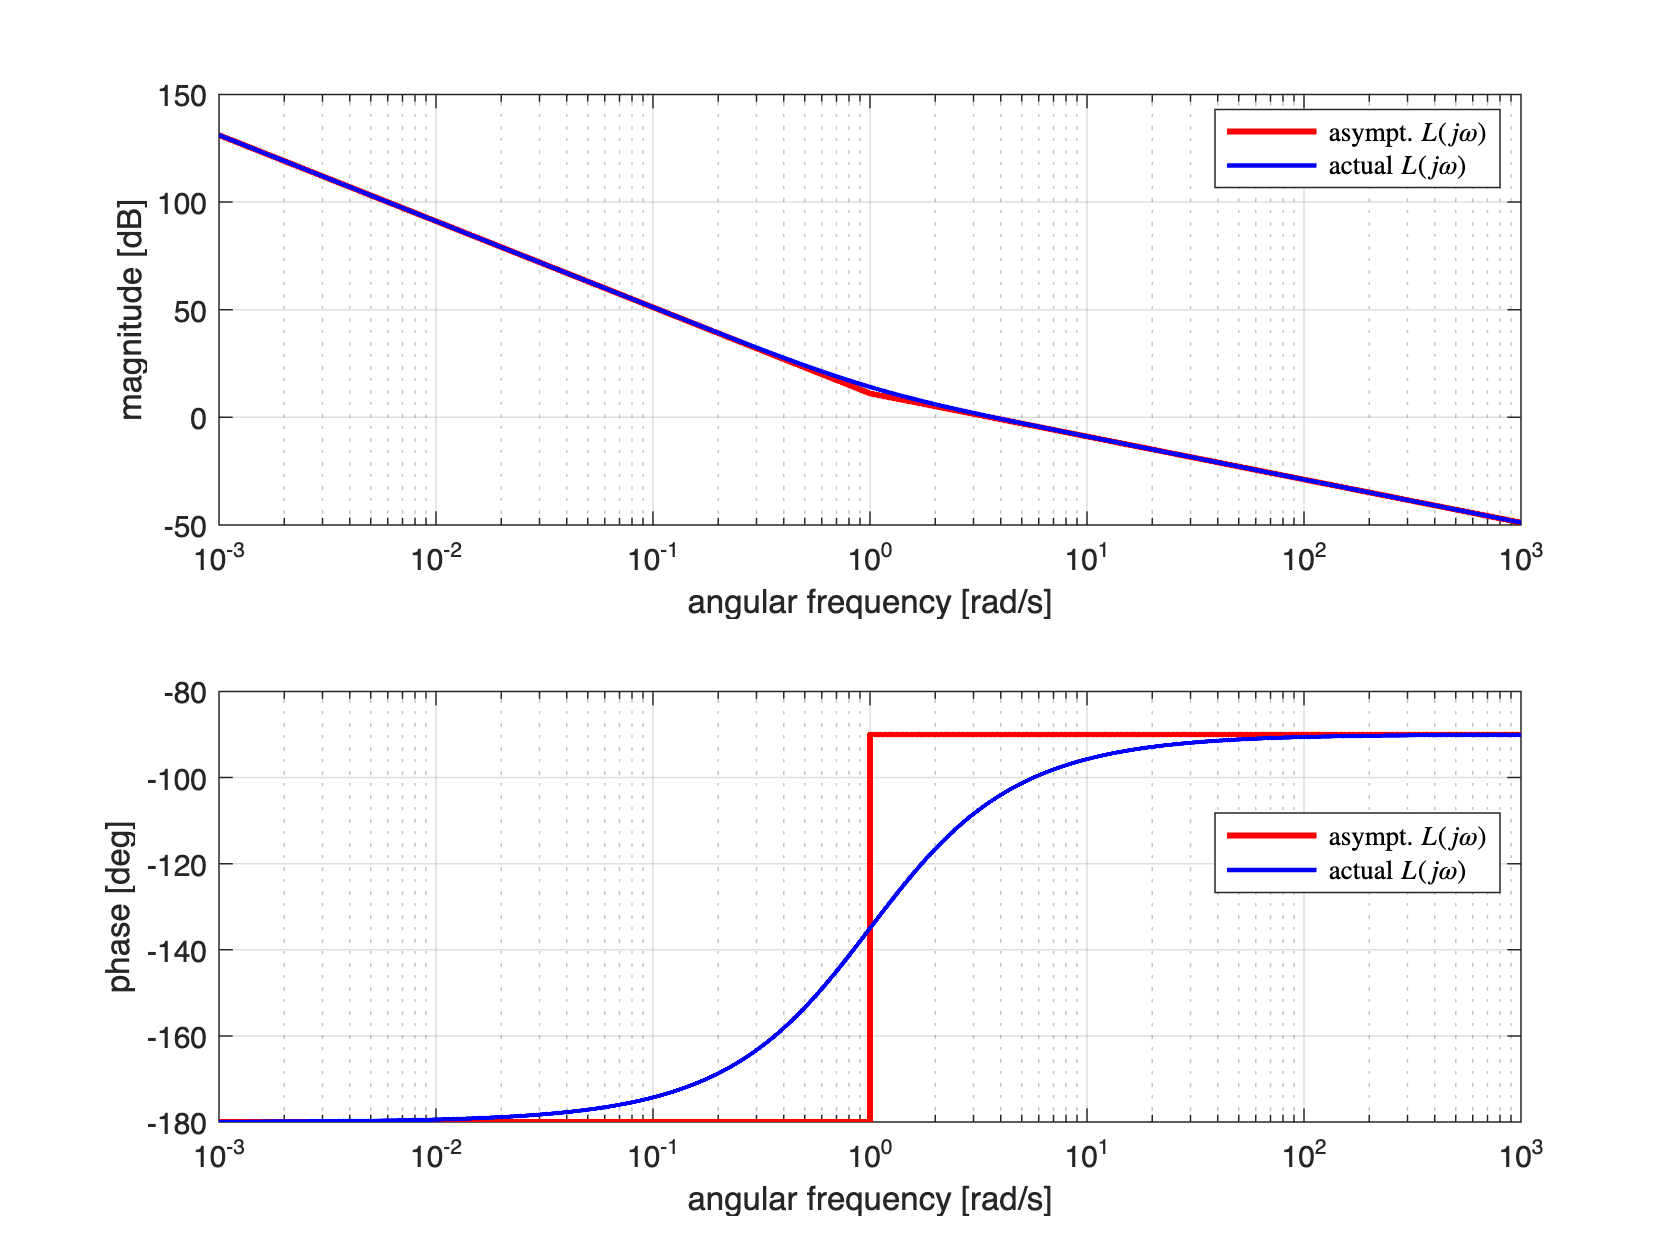

figure('Units','centimeters','Position',[0.5, 0.5, 27,24]);
[ha1, ha2] = drawBodediagrams(Ls2);
legend(ha1, 'asympt. $L(j \omega)$', 'actual $L(j \omega)$', ...
        'Interpreter', 'latex', 'location', 'best')
legend(ha2, 'asympt. $L(j \omega)$', 'actual $L(j \omega)$', ...
        'Interpreter', 'latex', 'location', 'best')

Let's compute the stability margins

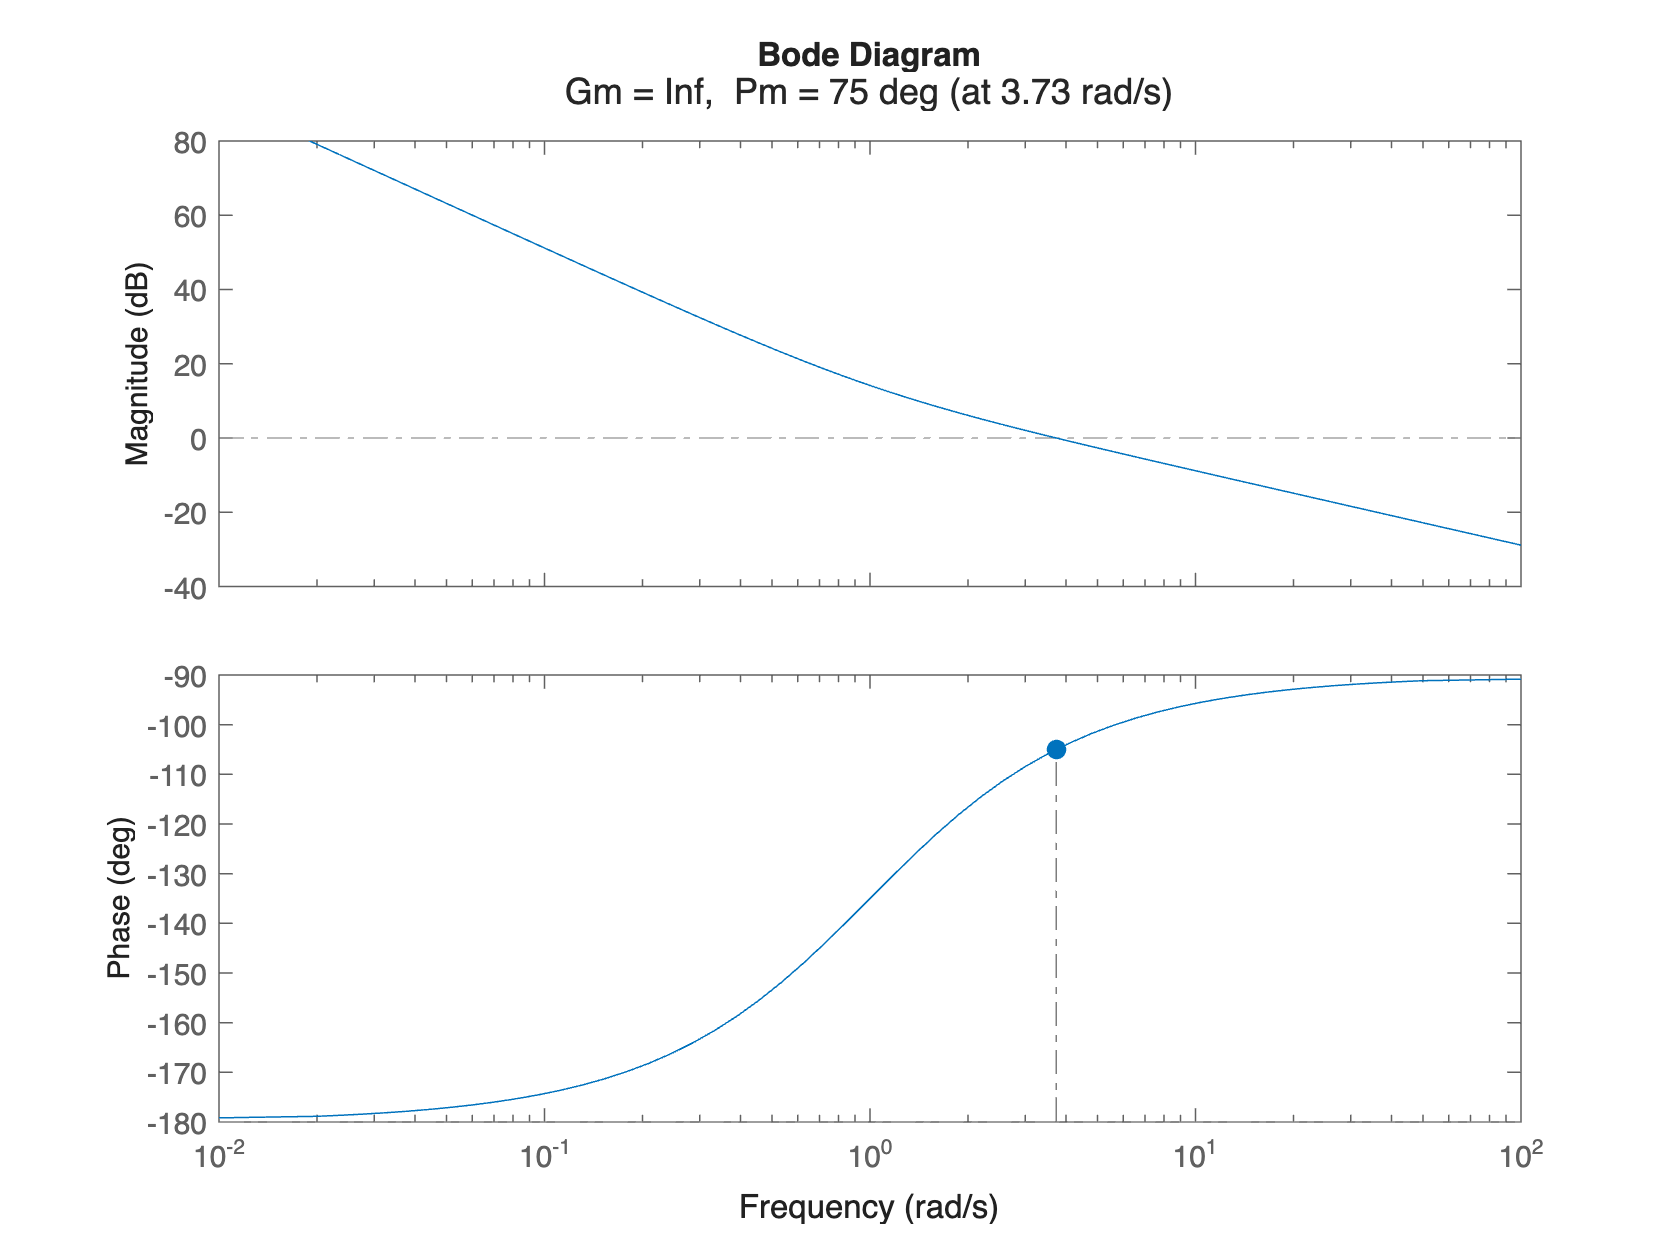

figure; margin(Ls2)

### Fine Tuning Using the ControlSystemDesigner

controlSystemDesigner(Gs, Cs2)

There is no need to further tuning of the controller. 

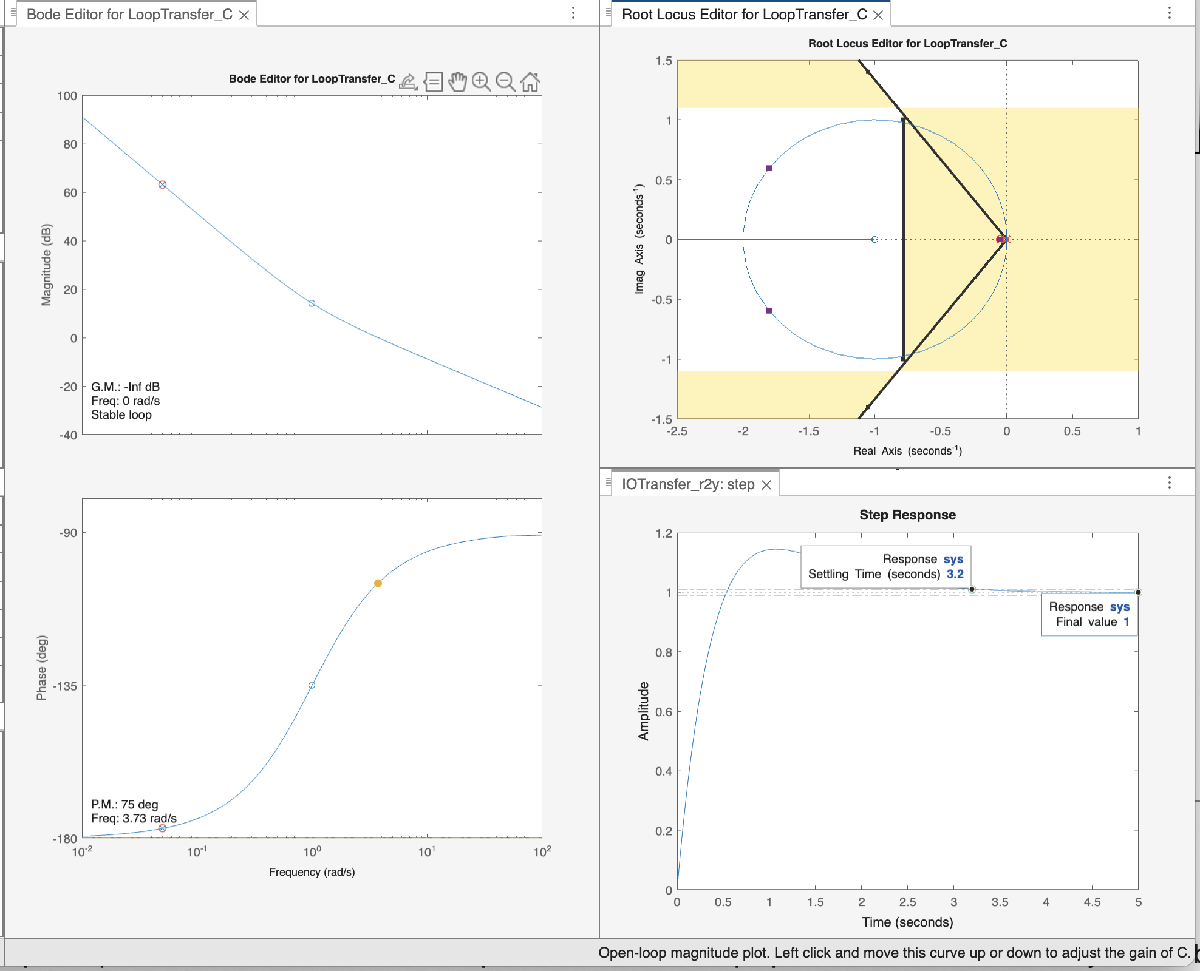

The session MAT file corresponding to the Figure is `SOL2_ControlSystemDesignerSession.mat` .